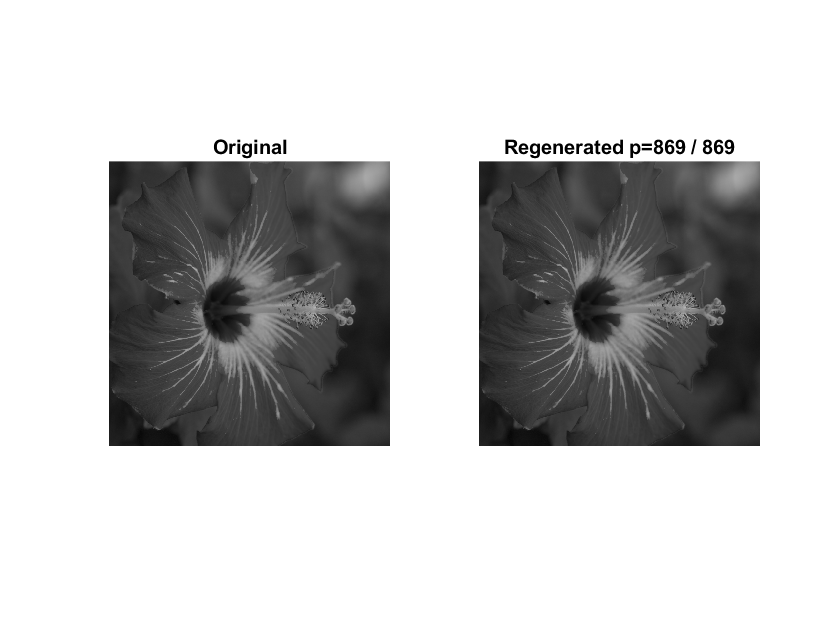

% Use PCA to break apart grayscale image into components, and regenerate an 
% image using sub-portions of those components (essentially image compression)

%% Load image
img = imread('MicrosoftTeams-image (1).png');

%% Get grayscale image
gray = rgb2gray(img);
[r,c] = size(gray); 

%% Visualize Original Image
 figure(1);
 subplot(1,2,1);
 imshow(gray);
 title('Original');

%% Do SVD on grayscale NxN matrix

gray = imresize(gray,[max(r,c),max(r,c)],'bicubic');
shape = size(gray);
[U,S,V] = svd(im2double(gray));

%% Contains sub-portion of components
Ug = zeros(shape);
Sg = zeros(shape);
Vgt = zeros(shape);
Vt = V'; % Keep track of transposed V, easier than transposing each time

%% Regenerate from components 
for p = 1:size(gray,1)
%     p = 10; % How many rows to take from original matrix

    % Create regenerated image
    Ug(:, 1:p) = U(:, 1:p);
    Sg(1:p, 1:p) = S(1:p, 1:p);
    Vgt(1:p, :) = Vt(1:p, :);
    regenerated_img = Ug*Sg*Vgt;

    %% Visualize
     subplot(1,2,2);
     regenerated_img = imresize(regenerated_img,[r,c]);
     imshow(regenerated_img);
     title(sprintf('Regenerated p=%d / %d', p,size(gray,1) ));
     pause(0.5);

    %% Save to file
    %imwrite(regenerated_img,sprintf('PCA_cat_%d.png', p),'png');
end